per = 10

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_dissatisied = 2

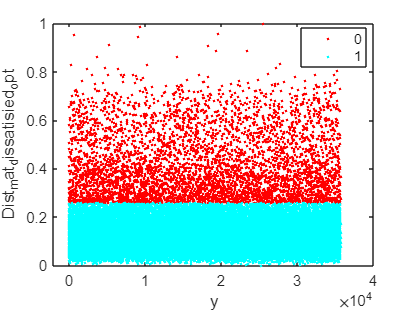

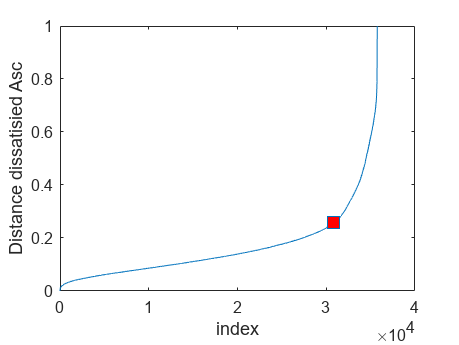

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_satisfied = 5

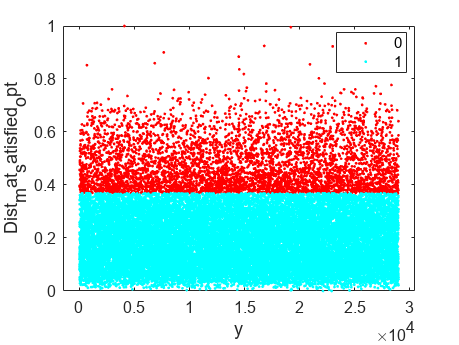

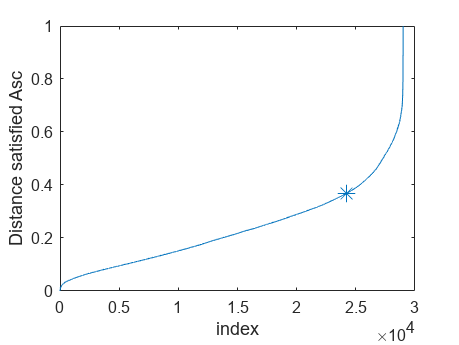

per = 10

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_dissatisied = 3

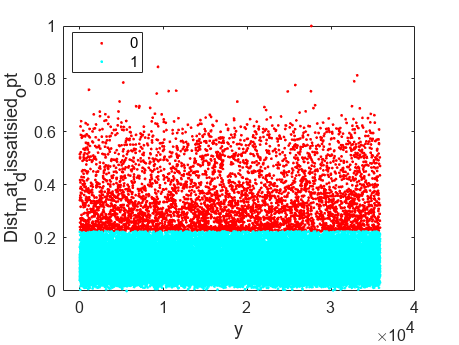

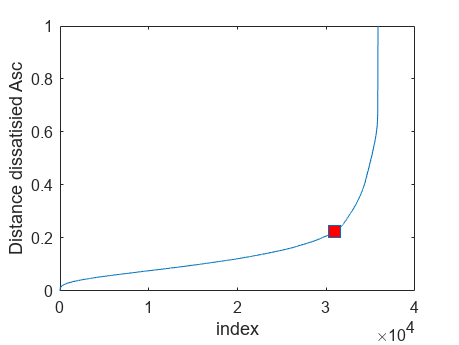

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_satisfied = 3

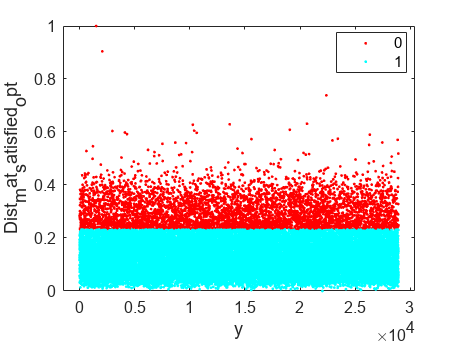

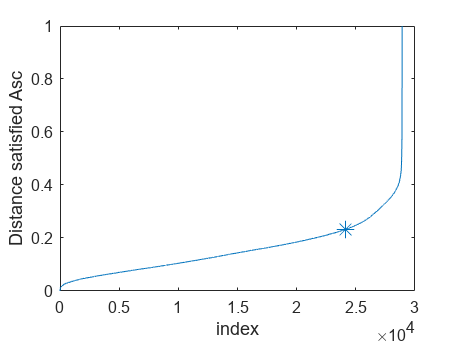

per = 10

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_dissatisied = 2

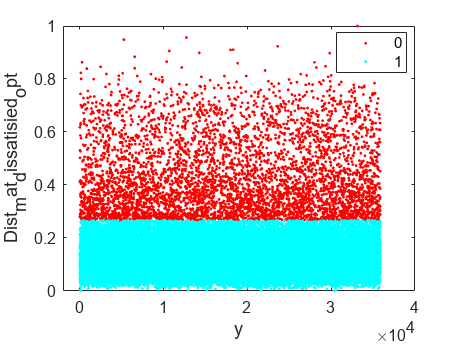

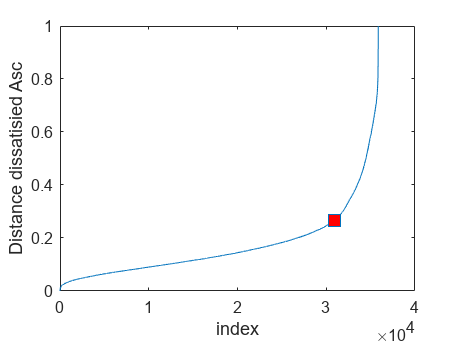

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_satisfied = 3

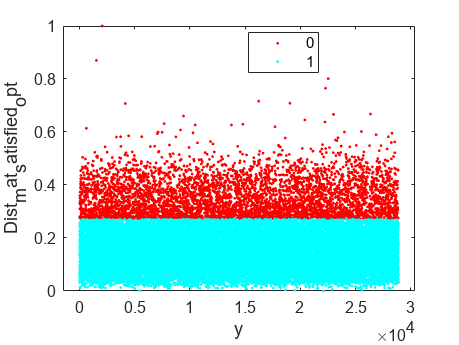

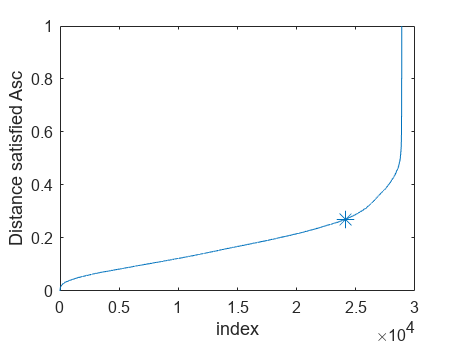

per = 10

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_dissatisied = 3

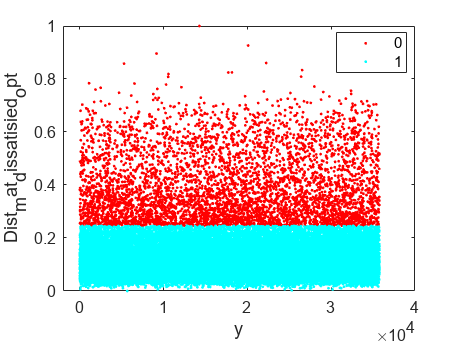

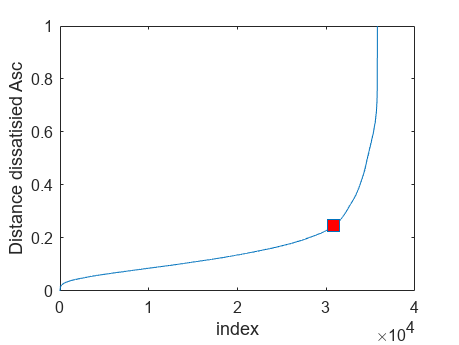

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 


optrank_satisfied = 3

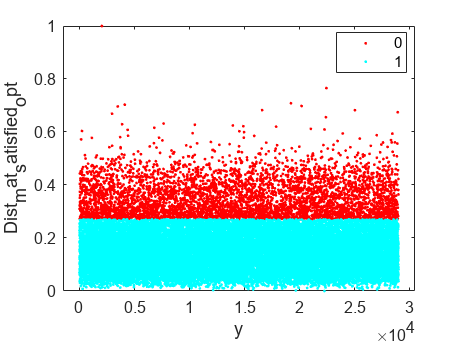

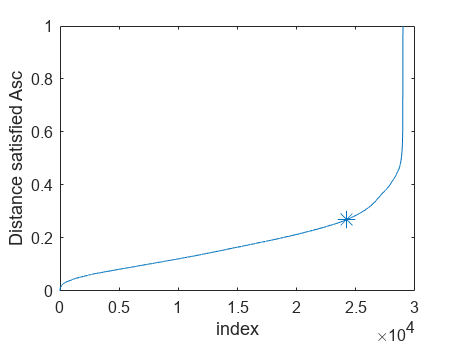

for j = [7,8,9,10]
    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\airline\split1\per0\airline_misclass_per_0.csv",",",1);
    per =10%[20,10,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\airline\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)


        my_file = strcat('airline_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        dissatisied=File(File(:,23)==1,1:22);
        T_dissatisied=dissatisied.';
       


        satisfied=File(File(:,23)==2,1:22);
        T_satisfied=satisfied.';


        folder_l1=strcat('ACE_dist_3optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5];

        error_dissatisied = nan(size(ranks));
        numdissatisied=length(T_dissatisied);
        Dist_mat_dissatisied_array_asc=nan(length(ranks),numdissatisied);
        threshold_rank_dissatisied=nan(size(ranks));
        elbow_indx_rank_dissatisied=nan(size(ranks));

        for i = ranks
            fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\airline\

            T_dissatisied_temp=T_dissatisied;
            Dist_mat_dissatisied=[];


            BF_dissatisied=l1pca_BF(T_dissatisied,i,1,10,10,'');
            for k = 1 : numdissatisied
                A=T_dissatisied(:,k);
                Dist_mat_dissatisied(k)=norm((A-(BF_dissatisied*BF_dissatisied.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_dissatisied,[],"all");
            max_val=max(Dist_mat_dissatisied,[],"all");
            Dist_mat_dissatisied= Dist_mat_dissatisied-min_val;%]/[max_val-min_val]
            Dist_mat_dissatisied=Dist_mat_dissatisied /(max_val-min_val);


            Dist_mat_dissatisied_array_asc(i,:)=Dist_mat_dissatisied;
            [Dist_mat_dissatisied_asc,Indx_dissatisied]=sort(Dist_mat_dissatisied,"ascend");


            [elbow_dissatisied_err_angle,elbow_indx_dissatisied]=knee_pt_angle((Dist_mat_dissatisied_asc));

            error_dissatisied(i)=elbow_dissatisied_err_angle;
            threshold_rank_dissatisied(i)=Dist_mat_dissatisied_asc(elbow_indx_dissatisied);
            elbow_indx_rank_dissatisied(i)=elbow_indx_dissatisied;

        end

        [~,optrank_dissatisied]= max(error_dissatisied)

        Dist_mat_dissatisied_opt=Dist_mat_dissatisied_array_asc(optrank_dissatisied,:);
        threshold_dist_dissatisied= threshold_rank_dissatisied(optrank_dissatisied);
        elbow_indx_dissatisied_opt=elbow_indx_rank_dissatisied(optrank_dissatisied);

        ind_O_dissatisied=find(Dist_mat_dissatisied_opt>threshold_dist_dissatisied);
        ind_I_dissatisied=find(Dist_mat_dissatisied_opt<=threshold_dist_dissatisied);


        cluster_dissatisied=zeros(size(Dist_mat_dissatisied_opt));
        cluster_dissatisied(ind_I_dissatisied)=1;
        figure
        y= 1:1:length(dissatisied);
        numGroups = length(unique(cluster_dissatisied));
        gscatter(y,Dist_mat_dissatisied_opt,cluster_dissatisied,hsv(numGroups))

        figure
        plot(sort(Dist_mat_dissatisied_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_dissatisied_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel("Distance dissatisied Asc")
        ind_O_dissatisied;


        T_dissatisied_temp(:,ind_O_dissatisied)=[];
        length(T_dissatisied_temp);
      

        Final_dissatisied=T_dissatisied_temp';
        cdissatisied=1*ones(size(Final_dissatisied,1),1);
        Final_dissatisied=[Final_dissatisied cdissatisied];

        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_satisfied = nan(size(ranks));
        numsatisfied=length(T_satisfied);
        Dist_mat_satisfied_array_asc=nan(length(ranks),numsatisfied);
        threshold_rank_satisfied=nan(size(ranks));
        elbow_indx_rank_satisfied=nan(size(ranks));

        for i = ranks
            fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\airline\

            T_satisfied_temp=T_satisfied;
            Dist_mat_satisfied=[];


            BF_satisfied=l1pca_BF(T_satisfied,i,1,10,10,'');
            for k = 1 : numsatisfied
                A=T_satisfied(:,k);
                Dist_mat_satisfied(k)=norm((A-(BF_satisfied*BF_satisfied.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_satisfied,[],"all");
            max_val=max(Dist_mat_satisfied,[],"all");
            Dist_mat_satisfied= Dist_mat_satisfied-min_val;%]/[max_val-min_val]
            Dist_mat_satisfied=Dist_mat_satisfied /(max_val-min_val);


            Dist_mat_satisfied_array_asc(i,:)=Dist_mat_satisfied;
            [Dist_mat_satisfied_asc,Indx_satisfied]=sort(Dist_mat_satisfied,"ascend");


            [elbow_satisfied_err_angle,elbow_indx_satisfied]=knee_pt_angle(Dist_mat_satisfied_asc);

            error_satisfied(i)=elbow_satisfied_err_angle;
            threshold_rank_satisfied(i)=Dist_mat_satisfied_asc(elbow_indx_satisfied);
            elbow_indx_rank_satisfied(i)=elbow_indx_satisfied;

        end

        [~,optrank_satisfied]= max(error_satisfied)

        Dist_mat_satisfied_opt=Dist_mat_satisfied_array_asc(optrank_satisfied,:);
        threshold_dist_satisfied= threshold_rank_satisfied(optrank_satisfied);
        elbow_indx_satisfied_opt=elbow_indx_rank_satisfied(optrank_satisfied);

        ind_O_satisfied=find(Dist_mat_satisfied_opt>threshold_dist_satisfied);
        ind_I_satisfied=find(Dist_mat_satisfied_opt<=threshold_dist_satisfied);


        cluster_satisfied=zeros(size(Dist_mat_satisfied_opt));
        cluster_satisfied(ind_I_satisfied)=1;
        figure
        y= 1:1:length(satisfied);
        numGroups = length(unique(cluster_satisfied));
        gscatter(y,Dist_mat_satisfied_opt,cluster_satisfied,hsv(numGroups))

        figure
        plot(sort(Dist_mat_satisfied_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_satisfied_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel("Distance satisfied Asc")
        ind_O_satisfied;


        T_satisfied_temp(:,ind_O_satisfied)=[];
        length(T_satisfied_temp);

        Final_satisfied=T_satisfied_temp';

        csatisfied=2*ones(size(Final_satisfied,1),1);
        Final_satisfied=[Final_satisfied csatisfied];


        cd C:\Users\shukl\Documents\GitHub\airline\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_dissatisied.',Final_satisfied.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:23)=  M.colheaders;
        filel1pca=strcat('airline_misclass_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca);
    end
end